## PART 1: KINEMATICS

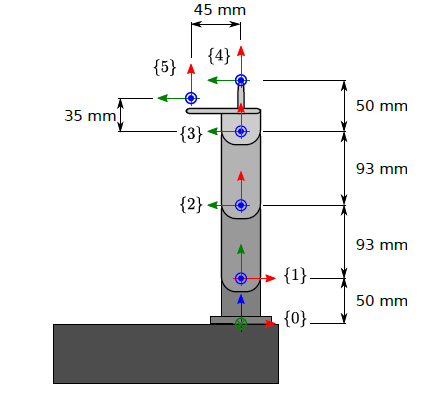

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;
% % Uncomment for symbolic representation
syms t1 t2 t3 t4 

% {0} -> {1}
T01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) L01;
       0 0 0 1];
% {1} -> {2}
T12 = [cos(t2) -sin(t2) 0 L12;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];
% {2} -> {3}
T23 = [1 0 0 L23;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {4}
T34 = [1 0 0 L34;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {5}
T35 = [1 0 0 L35;
       0 1 0 L45;
       0 0 1 0;
       0 0 0 1];

% Transformation from {0} to {4}
T04 = T01*T12*T23*T34

$$T04 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & -\sin\left(t_{2}\right) & 0 & 143\,\cos\left(t_{2}\right)+93\\ \cos\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{1}\right)\,\cos\left(t_{2}\right) & -\sin\left(t_{1}\right) & 143\,\cos\left(t_{1}\right)\,\sin\left(t_{2}\right)\\ \sin\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{2}\right)\,\sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 143\,\sin\left(t_{1}\right)\,\sin\left(t_{2}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Transformation from {0} to {5}
T05 = T01*T12*T23*T35

$$T05 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & -\sin\left(t_{2}\right) & 0 & 128\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)+93\\ \cos\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{1}\right)\,\cos\left(t_{2}\right) & -\sin\left(t_{1}\right) & 45\,\cos\left(t_{1}\right)\,\cos\left(t_{2}\right)+128\,\cos\left(t_{1}\right)\,\sin\left(t_{2}\right)\\ \sin\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{2}\right)\,\sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 45\,\cos\left(t_{2}\right)\,\sin\left(t_{1}\right)+128\,\sin\left(t_{1}\right)\,\sin\left(t_{2}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

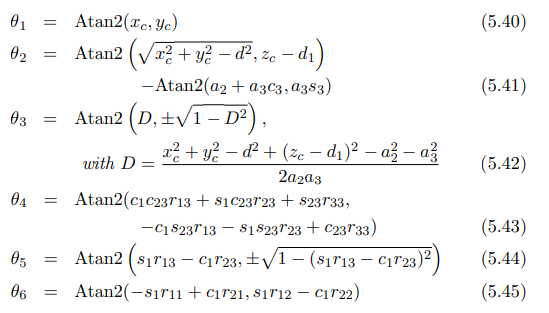

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(t2) -sin(t2) 0 0;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



t1 = atan2(xc,yc);

t3 = atan2(D, sqrt(1-D^2));

t2 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01);

R01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(t2) -sin(t2) 0 0;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;


t4 =atan2(cos(t1)*cos(t2+t3)*R(1,3) + sin(t1)*cos(t2+t3)*R(2,3) + sin(t2+t3)*R(3,3), -cos(t1)*sin(t2+t3)*R(1,3) - sin(t1)*sin(t2+t3)*R(2,3)+cos(t2+t3)*R(3,3));








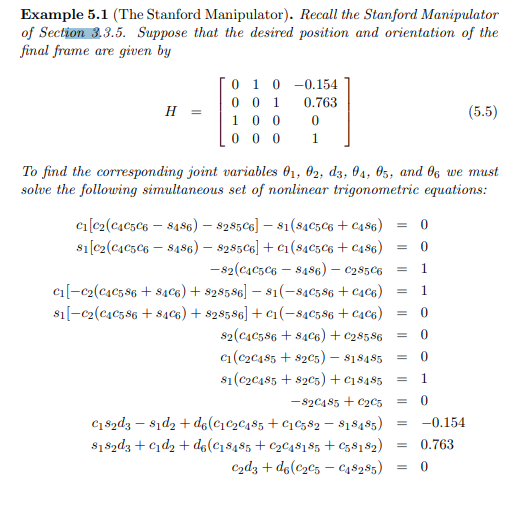

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**